# 2D Rectangle Mesh Simulation (Version 1.3)

## Update

V 1.3 更新日志：

1.修复了NIRFAST Toolbox中的部分已知错误，使图像重建功能得以正常运行

V 1.2 更新日志：

1.可以自由修改**发射极**（source）与**接收极**（detector）的位置

2.增加了对**Jacobi矩阵**的分析程序

3.删除了一些非必要的变量

## Introduction

该仿真使用**NIRFAST** **Toolbox**实现，使用**有限元方法**（**FEM**）仿真光在组织中的传播过程。仿真区域为一个基于**3层2维大脑模型**（**three-layered two-dimensional brain model**）的矩形区域。3层2维大脑模型认为大脑由如下组分构成：**皮肤/头皮层**（**skin/scalp layer**）、**头骨层**（**skull layer**）与**大脑层**（**brain layer**，包含**灰质与白质**），各层相关参数如下表所示：

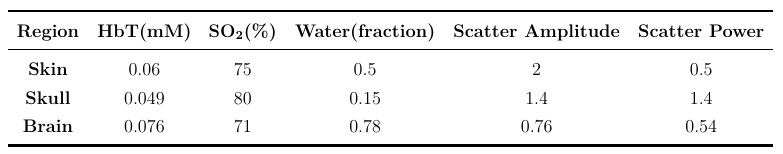

其中**HbT**为总血红蛋白含量，**SO2**为血氧饱和度，若记**Hb**为**脱氧血红蛋白**（**deoxyHb**），**HbO2**为**氧合血红蛋白**（**HbO**），则成立关系：


$$\text{Hb}_\text{T}=\text{Hb}+\text{HbO}_2,~\text{SO}_2=\text{HbO}_2/\text{Hb}_\text{T}\times 100\%$$


在本仿真中，我们取定**水**、**氧合血红蛋白**与**脱氧血红蛋白**作为主要的发色团。

仿真所使用的MATLAB版本为**R2020b**。

## Create the 2D Rectangle Mesh

 在MATLAB的命令行窗口中键入：

运行**NIRFAST GUI**，进行网格文件（**Mesh**）的创建：

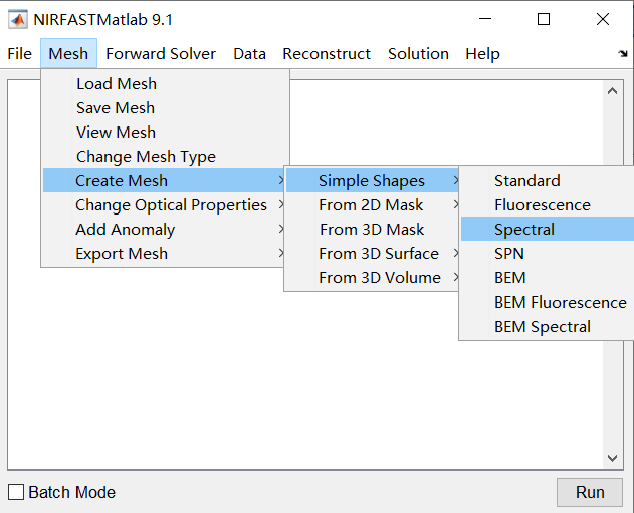

顺次点击**Mesh->Create Mesh->Simple Shapes->Spectral**，创建一个**分光类型**（**Spectral**）的网格文件，分光类型指使用若干给定波长光进行入射与采集。

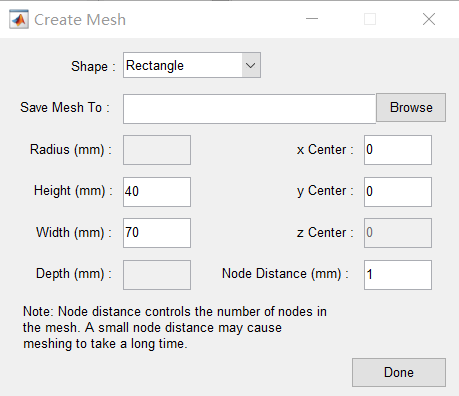

进而我们可创建一个**2D矩形网格**（**Rectangle**），此处我们设定其长为**100mm**，宽为**40mm**，结点距离为**1mm**（结点距离一般决定了仿真的精度，距离越小，精度越高）。参数设置完成后，点击**Done**生成网格文件：

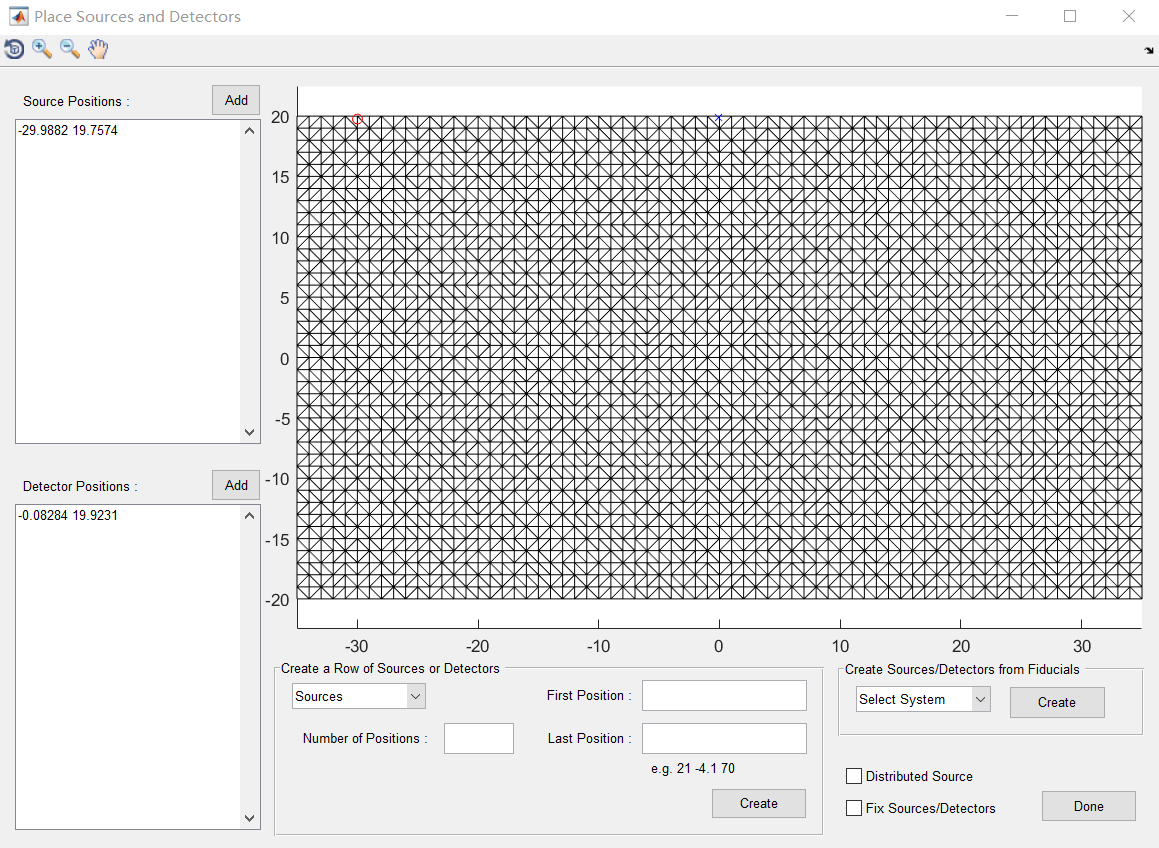

生成网格文件后，我们可使用**Add**按钮，使用光标在网格上添加光波的**发射极**（**Source**）与**探测极**（**Detector**），或也可直接使用坐标进行设定，此处我们仅设置一对光极。完成光极设置后，点击**Done**完成网格文件的生成：

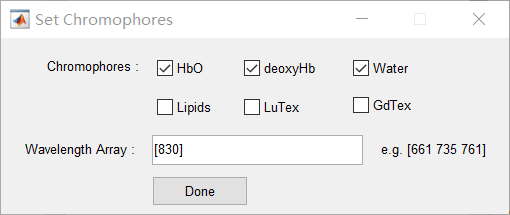

此后，我们可在上图窗口设置仿真所考查的**发色团**（**Chromophores**），并设定仿真的光波波长，此处我们设置仿真波长为单波长**830nm**，点击**Done**完成参数设置。

以下，在命令行窗口中键入：

可用于查看网格文件，同时，在命令行窗口中键入：

对网格文件进行保存。

## Load the Mesh

本节对网格文件进行载入：

clear all % 清空工作区内存中的变量
clc % 清空之前程序在终端的输出
mesh=load_mesh('C:\Users\86181\Desktop\NIRFAST\2D_Rec_1s1d\2D_Rec_1s1d');%由于MATLAB版本原因，此处可能不支持相对路径

Moving Sources
Moving Detectors


%mesh=load_mesh('C:\Users\86181\Desktop\NIRFAST\Rectangle-spec-mesh');
mesh.source.coord%显示发射极坐标

ans =   -45.0000   19.1700


mesh.meas.coord%显示探测极坐标

ans =     45    20


%计算探测极与发射极间的距离
disp(['The distance between source and detector is ', num2str(sqrt((mesh.source.coord(1)-mesh.meas.coord(1)).^2+(mesh.source.coord(2)-mesh.meas.coord(2)).^2)),'.']);

The distance between source and detector is 90.0038.


## Change the Position of Source/Detector (Optional)

本节可以对**发射极**（source）与**接收极**（detector）的位置进行修改。注意，发射极与接收极一般必须处于mesh的边界上（在PPT中有更具体的讨论），因此对本仿真而言，仅能调整发射极与接收极的**x坐标**：

x_of_source=-45;
x_of_detector=45;
mesh.source.coord(1)=x_of_source;
mesh.meas.coord(1)=x_of_detector;
[ind,int_func] = mytsearchn(mesh,mesh.meas.coord(:,1:2));%2维情形，3维需要改为[ind,int_func] = mytsearchn(mesh,mesh.meas.coord);
mesh.meas.int_func = [ind int_func];
clear ind int_func x_of_detector x_of_source

## Change the WaveLength (Optional)

本节可以进一步对仿真光波长进行修改：

wv=[830];%给定修改后的光波长
mesh.wv=wv;

## Define the Region

本节将利用3层大脑模型对2D矩形区域进行分层：

%调整头皮层、头骨层与大脑层的厚度
H_of_skin=5;
H_of_skull=8;
H_of_brain=27;
%判断厚度参数是否有效
if (H_of_brain+H_of_skin+H_of_skull)~=(max(mesh.nodes(:,2))-min(mesh.nodes(:,2)))
    error('Wrong setting, the sum of the thickness of each layer is not equal to the width of the mesh.');
end
%寻找坐标边界值
nn=size(mesh.nodes,1);
x_max=max(mesh.nodes(:,1));
x_min=min(mesh.nodes(:,1));
y_max=max(mesh.nodes(:,2));
y_min=min(mesh.nodes(:,2));
for i=1:nn
    if mesh.nodes(i,2)>=(y_max-H_of_skin)%如果结点位于头皮层
        mesh.region(i)=1;
    elseif mesh.nodes(i,2)>=(y_max-H_of_skin-H_of_skull)%如果结点位于头骨层
        mesh.region(i)=2;
    else %如果结点位于大脑层
        mesh.region(i)=3;
    end
end

## Parameter Assignment

本节将对各层参数进行赋值：

% Skin (Region 1)
values.sa = 2;
values.sp = 0.5;
values.HbO =  0.045;
values.deoxyHb = 0.015;
values.Water = 0.5;
mesh = set_mesh(mesh,1,values);
%Skull (Region 2)
values.sa = 1.4;
values.sp = 1.4;
values.HbO =  0.0392;
values.deoxyHb = 0.0098;
values.Water = 0.15;
mesh = set_mesh(mesh,2,values);
%Brian (Region 3)
values.sa = 0.76;
values.sp = 0.76;
values.HbO =  0.054;
values.deoxyHb = 0.022;
values.Water = 0.78;
mesh = set_mesh(mesh,3,values);
clear values;

赋值完成后，可对2D矩形区域进行可视化：

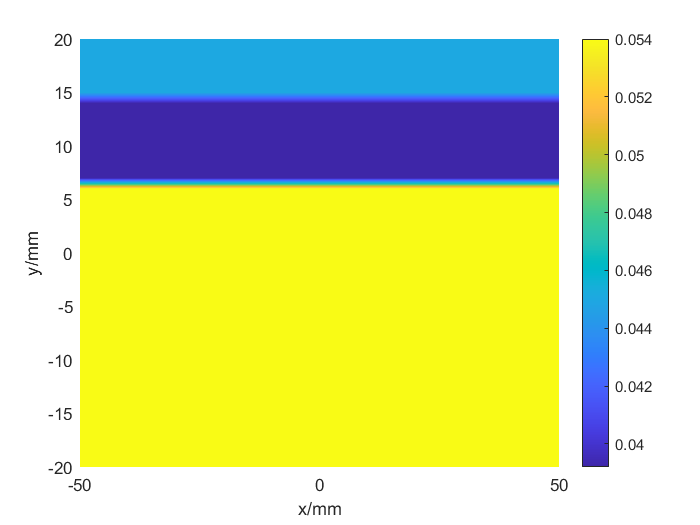

[x,y]=meshgrid(min(mesh.nodes(:,1)):1:max(mesh.nodes(:,1)),min(mesh.nodes(:,2)):1:max(mesh.nodes(:,2)));
F=scatteredInterpolant(mesh.nodes(:,1),mesh.nodes(:,2),mesh.conc(:,1));
val=F(x,y);
figure; surf(squeeze(x),squeeze(y),squeeze(val)); 
view(0,90); shading interp; colorbar; axis tight
xlabel('x/mm'); ylabel('y/mm');

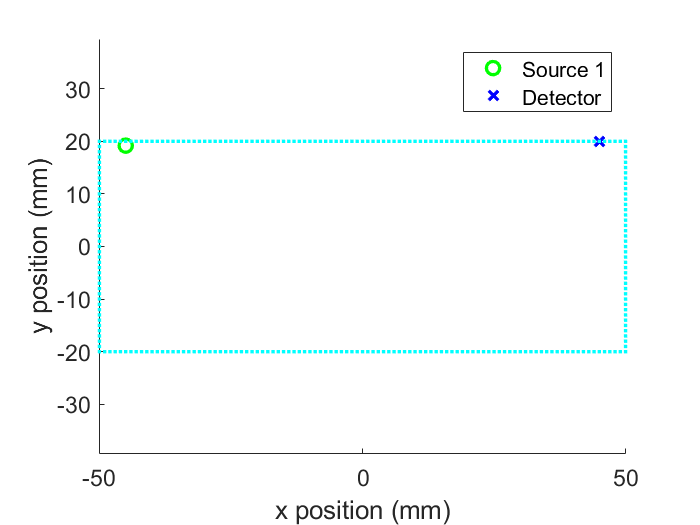

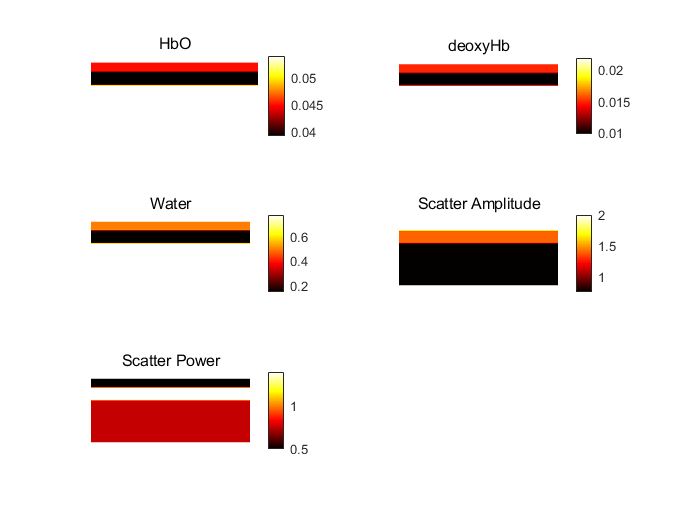

clear x y val
plotmesh(mesh,1);%调用系统内置的可视化函数

## Generate Boundary Data (Optional)

本节可以分别给出**连续波近红外（CW-NIRS）**与**频域近红外（FD-NIRS）**的仿真数据，但在生成Jacobi矩阵时无需使用这些数据：

freq=140;%设定调制频率
data_CW=femdata(mesh,0);%CW-NIRS的仿真数据

Calculating data for: 830 nm


data_FD=femdata(mesh,freq);%FD-NIRS的仿真数据

Calculating data for: 830 nm


##     Caculate Jacobian Matrix

本节将对Jacobi矩阵进行计算，在此之前，对程序给出的Jacobi矩阵形式进行说明：

一般来说，若网格文件中存在$n$个结点，$m$对光极，则对应的Jacobi矩阵可记作：


$$\displaystyle J=\frac{\partial \Phi}{\partial \mu}=\left[\begin{array}{ccccccccc}
\frac{\partial\ln I_1}{\partial \kappa_1}&\frac{\partial\ln I_1}{\partial \kappa_2}&\cdots&\frac{\partial\ln I_1}{\partial \kappa_n}&;&\frac{\partial\ln I_1}{\partial \mu_{a1}}&\frac{\partial\ln I_1}{\partial \mu_{a2}}&\cdots&\frac{\partial\ln I_1}{\partial \mu_{an}}\\
\frac{\partial\theta_1}{\partial \kappa_1}&\frac{\partial\theta_1}{\partial \kappa_2}&\cdots&\frac{\partial\theta_1}{\partial \kappa_n}&;&\frac{\partial\theta_1}{\partial \mu_{a1}}&\frac{\partial\theta_1}{\partial \mu_{a2}}&\cdots&\frac{\partial\theta_1}{\partial \mu_{an}}\\
\frac{\partial\ln I_2}{\partial \kappa_1}&\frac{\partial\ln I_2}{\partial \kappa_2}&\cdots&\frac{\partial\ln I_2}{\partial \kappa_n}&;&\frac{\partial\ln I_2}{\partial \mu_{a1}}&\frac{\partial\ln I_2}{\partial \mu_{a2}}&\cdots&\frac{\partial\ln I_2}{\partial \mu_{an}}\\
\frac{\partial\theta_2}{\partial \kappa_1}&\frac{\partial\theta_2}{\partial \kappa_2}&\cdots&\frac{\partial\theta_2}{\partial \kappa_n}&;&\frac{\partial\theta_2}{\partial \mu_{a1}}&\frac{\partial\theta_2}{\partial \mu_{a2}}&\cdots&\frac{\partial\theta_2}{\partial \mu_{an}}\\
\vdots&\vdots&\ddots&\vdots&;&\vdots&\vdots&\ddots&\vdots\\
\frac{\partial\ln I_m}{\partial \kappa_1}&\frac{\partial\ln I_m}{\partial \kappa_2}&\cdots&\frac{\partial\ln I_m}{\partial \kappa_n}&;&\frac{\partial\ln I_m}{\partial \mu_{a1}}&\frac{\partial\ln I_m}{\partial \mu_{a2}}&\cdots&\frac{\partial\ln I_m}{\partial \mu_{an}}\\
\frac{\partial\theta_m}{\partial \kappa_1}&\frac{\partial\theta_m}{\partial \kappa_2}&\cdots&\frac{\partial\theta_m}{\partial \kappa_n}&;&\frac{\partial\theta_m}{\partial \mu_{a1}}&\frac{\partial\theta_m}{\partial \mu_{a2}}&\cdots&\frac{\partial\theta_m}{\partial \mu_{an}}\\
\end{array}\right]$$


其中：


$$\Phi=[\ln I_1,~\theta_1,~\ln I_2,~\theta_2,\cdots,~\ln I_m,~\theta_m]^T$$


为$m$组光强与相位测量数据，同时：


$$\mu=[\kappa_1,~\kappa_2,\cdots,~\kappa_n;~\mu_{a1},~\mu_{a2},\cdots,~\mu_{an}]^T$$


为$n$个结点处的**扩散系数**$\kappa$（**Diffusion Coefficient**）与**吸收系数**$\mu_a$（**Absorption** **Coefficient**），而注意到：


$$\mu_a=[\varepsilon_1,~\varepsilon_2,~\varepsilon_3]\times\left[\begin{array}{c}c_1\\
c_2\\
c_3\end{array}\right],~\mu_s'=a\lambda^{-b}$$


其中$c_1,~c_2,~c_3$为3种发色团的浓度（**HbO/Hb/Water**），$\varepsilon_1,~\varepsilon_2,~\varepsilon_3$为3种发色团对应的吸收光谱，$a,~b$分别为**散射幅度**与**散射功率**，注意到$\kappa=1/3(\mu_a+\mu_s')$，因此进而可将$[\kappa,~\mu_a]$关联至$[c_1,~c_2,~c_3,~a,~b]$：


$$\left[\begin{array}{c}
\partial \Phi_1\\
\partial \Phi_2\\
\vdots\\
\partial \Phi_m\\
\end{array}\right]=\left[\begin{array}{ccccc}
J_{c_1,~1}&J_{c_2,~1}&J_{c_3,~1}&J_{a,~1}&J_{b,~1}\\
J_{c_1,~2}&J_{c_2,~2}&J_{c_3,~2}&J_{a,~2}&J_{b,~2}\\
\vdots&\vdots&\vdots&\vdots&\vdots\\
J_{c_1,~m}&J_{c_2,~m}&J_{c_3,~m}&J_{a,~m}&J_{b,~m}\\
\end{array}\right]\times\left[\begin{array}{c}
\partial c_1\\
\partial c_2\\
\partial c_3\\
\partial a\\
\partial b
\end{array}\right]$$


freq=140;%设定调制频率
J=jacobian(mesh,freq);

Calculating Jacobian for 830nm


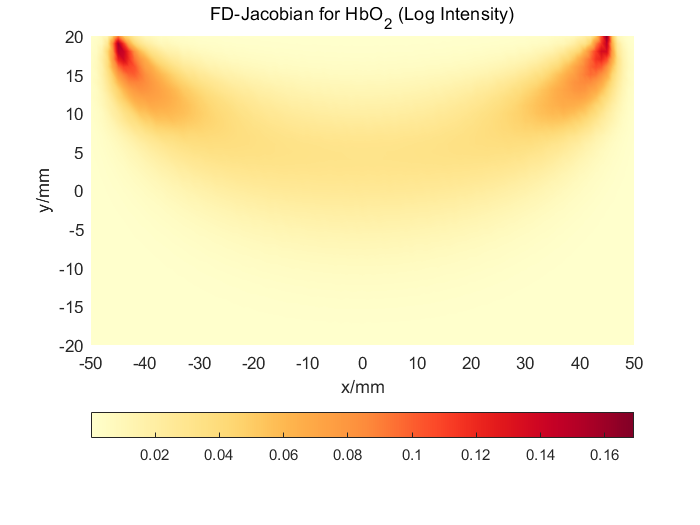

[x,y]=meshgrid(min(mesh.nodes(:,1)):1:max(mesh.nodes(:,1)),min(mesh.nodes(:,2)):1:max(mesh.nodes(:,2)));
%Jacobian for HbO
F=scatteredInterpolant(mesh.nodes(:,1),mesh.nodes(:,2),J(1,1:nn)'./mesh.support);
val=F(x,y);
figure; 
surf(squeeze(x),squeeze(y),abs(squeeze(val)));
colormap(othercolor('YlOrRd9'));%如果不需要颜色设定可删去该行
view(0,90); shading interp; c=colorbar;
c.Location = 'southoutside'; axis tight
xlabel('x/mm'); ylabel('y/mm');
title('FD-Jacobian for HbO_2 (Log Intensity)');

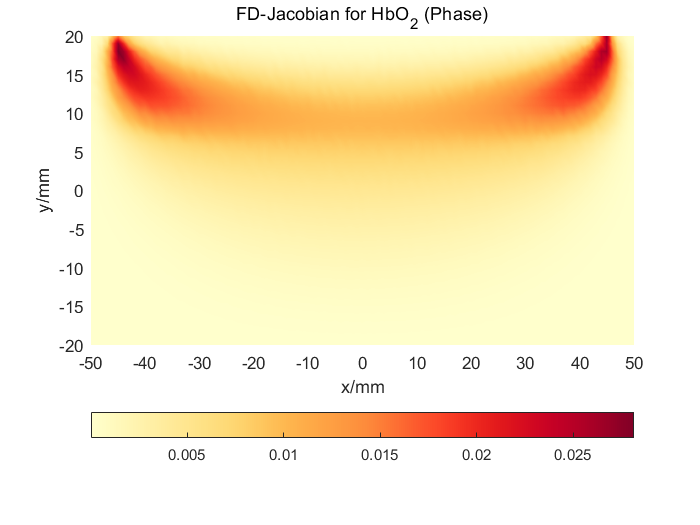

F=scatteredInterpolant(mesh.nodes(:,1),mesh.nodes(:,2),J(2,1:nn)'./mesh.support);
val=F(x,y);
figure; surf(squeeze(x),squeeze(y),abs(squeeze(val)));
colormap(othercolor('YlOrRd9'));%如果不需要颜色设定可删去该行
view(0,90); shading interp; c=colorbar;
c.Location = 'southoutside'; axis tight
xlabel('x/mm'); ylabel('y/mm');
title('FD-Jacobian for HbO_2 (Phase)');

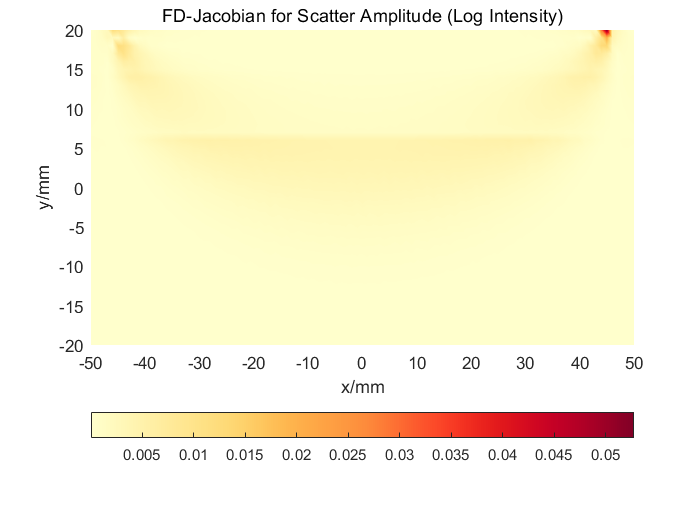

%Jacobian for Scatter Amplitude
F=scatteredInterpolant(mesh.nodes(:,1),mesh.nodes(:,2),J(1,3*nn+1:4*nn)'./mesh.support);
val=F(x,y);
figure; 
surf(squeeze(x),squeeze(y),abs(squeeze(val)));
colormap(othercolor('YlOrRd9'));%如果不需要颜色设定可删去该行
view(0,90); shading interp; c=colorbar;
c.Location = 'southoutside'; axis tight
xlabel('x/mm'); ylabel('y/mm');
title('FD-Jacobian for Scatter Amplitude (Log Intensity)');

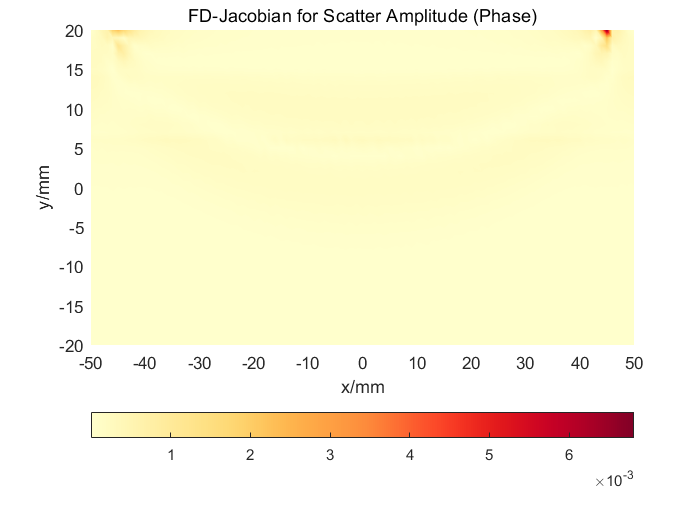

F=scatteredInterpolant(mesh.nodes(:,1),mesh.nodes(:,2),J(2,3*nn+1:4*nn)'./mesh.support);
val=F(x,y);
figure; surf(squeeze(x),squeeze(y),abs(squeeze(val)));
colormap(othercolor('YlOrRd9'));%如果不需要颜色设定可删去该行
view(0,90); shading interp; c=colorbar;
c.Location = 'southoutside'; axis tight
xlabel('x/mm'); ylabel('y/mm');
title('FD-Jacobian for Scatter Amplitude (Phase)');

clear val x y

## Jacobian Analysis

#### A.中线灵敏度-深度曲线绘制

x_of_source=-45;%设置仿真发射极初始位置
x_of_detector=45;%设置仿真接收极初始位置
mesh.source.coord(1)=x_of_source;
mesh.meas.coord(1)=x_of_detector;
[ind,int_func] = mytsearchn(mesh,mesh.meas.coord(:,1:2));%2维情形，3维需要改为[ind,int_func] = mytsearchn(mesh,mesh.meas.coord);
mesh.meas.int_func = [ind int_func];
clear ind int_func x_of_detector x_of_source
foot_step=9;%设置仿真步长
foot_size= abs(mesh.meas.coord(1)-mesh.source.coord(1))/foot_step;
figure;
h_figure=zeros(foot_step,2);
x_peak_dens=zeros(1,foot_step);
x_peak_phase=zeros(1,foot_step);
val_peak_dens=zeros(1,foot_step);
val_peak_phase=zeros(1,foot_step);
Int_dens=zeros(1,foot_step);
Int_phase=zeros(1,foot_step);
%fwhm_dens=zeros(1,foot_step);
%fwhm_phase=zeros(1,foot_step);
d_disc=zeros(1,foot_step);
for i=1:foot_step
J=jacobian(mesh,freq);
d_disc(foot_step+1-i)=abs(mesh.meas.coord(1)-mesh.source.coord(1));
mid_of_x=floor((mesh.source.coord(1)+mesh.meas.coord(1))*0.5);
[x,y]=meshgrid(x_min:1:x_max,y_min:1:y_max);
F=scatteredInterpolant(mesh.nodes(:,1),mesh.nodes(:,2),J(1,1:nn)'./mesh.support);
val=F(x,y); 
y_s=linspace(min(y(:,mid_of_x+(x_max-x_min)/2+1)),max(y(:,mid_of_x+(x_max-x_min)/2+1)),1000);
val_s=interp1(y(:,mid_of_x+(x_max-x_min)/2+1),val(:,mid_of_x+(x_max-x_min)/2+1),y_s,'spline');%提取中线灵敏度曲线，并进行插值
[val_peak_dens(foot_step+1-i),temp]=max(abs(val_s));
x_peak_dens(foot_step+1-i)=y_max-y_s(temp);%计算峰值深度
%Int_dens(foot_step+1-i)=trapz(y_s(1:((y_max-y_min-H_of_skull-H_of_skin)/(y_max-y_min)*1000)), ...
%    val_s(1:((y_max-y_min-H_of_skull-H_of_skin)/(y_max-y_min)*1000)))/trapz(y_s,val_s)*100;%计算位于大脑区域的灵敏度积分（相对值）
Int_dens(foot_step+1-i)=abs(trapz(y_s(1:((y_max-y_min-H_of_skull-H_of_skin)/(y_max-y_min)*1000)), ...
    val_s(1:((y_max-y_min-H_of_skull-H_of_skin)/(y_max-y_min)*1000))));%计算位于大脑区域的灵敏度积分（绝对值）
%fwhm_dens(foot_step+1-i)=fwhm(y_s,abs(val_s));
%h_figure(i,:)=plot(y_s,abs(val_s),'--',y(:,mid_of_x+(x_max-x_min)/2+1),abs(val(:,mid_of_x+(x_max-x_min)/2+1)),'.');%标记所有原始数据点
h_figure(i,:)=plot(y_s,mapminmax(abs(val_s),0,1),'--',y(:,mid_of_x+(x_max-x_min)/2+1),mapminmax(abs(val(:,mid_of_x+(x_max-x_min)/2+1))',0,1),'.');%标记所有原始数据点，并归一化
%h_figure(i,:)=plot(y_s,abs(val_s),'--',y_s(temp),abs(val_s(temp)),'k*');%仅标记最大值点
hold on
mesh.source.coord(1)=mesh.source.coord(1)+foot_size;%调整发射极位置，循环仿真
end
hold off
mesh.source.coord(1)=mesh.source.coord(1)-foot_size*foot_step;
%ylabel('Log Intensity/W\cdot mm^{-2} \cdot mM^{-1}'); xlabel('y/mm');
ylabel('Log Intensity (Normalized)'); xlabel('y/mm');
title('FD-Jacobian for HbO_2 at the Mid-Line (Log Intensity)');
lgd=legend([h_figure(1,1),h_figure(2,1),h_figure(3,1),...
    h_figure(4,1),h_figure(5,1),h_figure(6,1),...
    h_figure(7,1),h_figure(8,1),h_figure(9,1)], ...
    '90mm','80mm','70mm','60mm','50mm','40mm', ...
    '30mm','20mm','10mm','Location','northwest');
title(lgd,'Distance');
clear y_s val_s
figure;
for i=1:foot_step
J=jacobian(mesh,freq);
mid_of_x=floor((mesh.source.coord(1)+mesh.meas.coord(1))*0.5);
[x,y]=meshgrid(x_min:1:x_max,y_min:1:y_max);
F=scatteredInterpolant(mesh.nodes(:,1),mesh.nodes(:,2),J(2,1:nn)'./mesh.support);
val=F(x,y); 
y_s=linspace(min(y(:,mid_of_x+(x_max-x_min)/2+1)),max(y(:,mid_of_x+(x_max-x_min)/2+1)),1000);
val_s=interp1(y(:,mid_of_x+(x_max-x_min)/2+1),val(:,mid_of_x+(x_max-x_min)/2+1),y_s,'spline');%提取中线灵敏度曲线，并进行插值
[val_peak_phase(foot_step+1-i),temp]=max(abs(val_s));
x_peak_phase(foot_step+1-i)=y_max-y_s(temp);%计算峰值深度
%Int_phase(foot_step+1-i)=trapz(y_s(1:((y_max-y_min-H_of_skull-H_of_skin)/(y_max-y_min)*1000)), ...
%    val_s(1:((y_max-y_min-H_of_skull-H_of_skin)/(y_max-y_min)*1000)))/trapz(y_s,val_s)*100;%计算位于大脑区域的灵敏度积分（相对值）
Int_phase(foot_step+1-i)=abs(trapz(y_s(1:((y_max-y_min-H_of_skull-H_of_skin)/(y_max-y_min)*1000)), ...
    val_s(1:((y_max-y_min-H_of_skull-H_of_skin)/(y_max-y_min)*1000))));%计算位于大脑区域的灵敏度积分（绝对值）
%fwhm_phase(foot_step+1-i)=fwhm(y_s,abs(val_s));
%h_figure(i,:)=plot(y_s,abs(val_s),'--',y(:,mid_of_x+(x_max-x_min)/2+1),abs(val(:,mid_of_x+(x_max-x_min)/2+1)),'.');%标记所有原始数据点
h_figure(i,:)=plot(y_s,mapminmax(abs(val_s),0,1),'--',y(:,mid_of_x+(x_max-x_min)/2+1),mapminmax(abs(val(:,mid_of_x+(x_max-x_min)/2+1))',0,1),'.');%标记所有原始数据点，并归一化
%h_figure(i,:)=plot(y_s,abs(val_s),'--',y_s(temp),abs(val_s(temp)),'k*');%仅标记最大值点
hold on
mesh.source.coord(1)=mesh.source.coord(1)+foot_size;%调整发射极位置，循环仿真
end
hold off
mesh.source.coord(1)=mesh.source.coord(1)-foot_size*foot_step;
%ylabel('Phase/rad \cdot mM^{-1}'); 
ylabel('Phase (Normalized)'); xlabel('y/mm');
title('FD-Jacobian for HbO_2 at the Mid-Line (Phase)');
lgd=legend([h_figure(1,1),h_figure(2,1),h_figure(3,1),...
    h_figure(4,1),h_figure(5,1),h_figure(6,1),...
    h_figure(7,1),h_figure(8,1),h_figure(9,1)], ...
    '90mm','80mm','70mm','60mm','50mm','40mm', ...
    '30mm','20mm','10mm','Location','northwest');
title(lgd,'Distance');
clear y_s val_s lgd

#### 2.中线峰值灵敏度-光极距离曲线绘制

figure;
%归一化数据
d_s=linspace(min(d_disc),max(d_disc),1000);
val_peak_dens=mapminmax(val_peak_dens,0,1);
val_peak_phase=mapminmax(val_peak_phase,0,1);
val_s_dens=interp1(d_disc,val_peak_dens,d_s,'spline');
val_s_phase=interp1(d_disc,val_peak_phase,d_s,'spline');
h1=plot(d_s,val_s_dens,'--',d_disc,val_peak_dens,'ko');
hold on
h2=plot(d_s,val_s_phase,'--',d_disc,val_peak_phase,'ko');
xlabel('Distance/mm');
ylabel('Peak Value (Normalized)');
lgd=legend([h1(1) h2(1)],'Log Intensity','Phase','Location','northeast');
title(lgd,'Data Type');
%{
%非归一化数据
val_s_dens=interp1(d_disc,val_peak_dens,d_s,'spline');
val_s_phase=interp1(d_disc,val_peak_phase,d_s,'spline');
yyaxis left
h1=plot(d_s,val_s_dens,'--',d_disc,val_peak_dens,'ko');
ylabel('Peak Value (Log Intensity)/W\cdot mm^{-2} \cdot mM^{-1}');
yyaxis right
h2=plot(d_s,val_s_phase,'--',d_disc,val_peak_phase,'ko');
hold off
ylabel('Peak Value (Phase)/rad \cdot mM^{-1}');
xlabel('Distance/mm');
lgd=legend([h1(1) h2(1)],'Log Intensity','Phase','Location','northeast');
title(lgd,'Data Type');
%}
clear h1 h2 val_s_phase val_s_dens lgd

#### 3.中线峰值灵敏度深度-光极距离曲线绘制

figure;
J_s_dens=interp1(d_disc,x_peak_dens,d_s,'spline');
J_s_phase=interp1(d_disc,x_peak_phase,d_s,'spline');
h1=plot(d_s,J_s_dens,'--',d_disc,x_peak_dens,'ko');
hold on
h2=plot(d_s,J_s_phase,'--',d_disc,x_peak_phase,'ko');
hold off
ylabel('Peak Depth/mm'); xlabel('Distance/mm');
lgd=legend([h1(1) h2(1)],'Log Intensity','Phase','Location','northwest');
title(lgd,'Data Type');
clear h1 h2 J_s_phase J_s_dens lgd

#### 4.大脑区域灵敏度积分-光极距离曲线绘制

figure;
%{
%归一化的积分
Int_s_dens=interp1(d_disc,Int_dens,d_s,'spline');
Int_s_phase=interp1(d_disc,Int_phase,d_s,'spline');
h1=plot(d_s,Int_s_dens,'--',d_disc,Int_dens,'ko');
hold on
h2=plot(d_s,Int_s_phase,'--',d_disc,Int_phase,'ko');
hold off
ylabel('Integral Value (Normalized)/%'); xlabel('Distance/mm');
lgd=legend([h1(1) h2(1)],'Log Intensity','Phase','Location','northwest');
title(lgd,'Data Type');
%}
%未归一化的积分
Int_s_dens=interp1(d_disc,Int_dens,d_s,'spline');
Int_s_phase=interp1(d_disc,Int_phase,d_s,'spline');
yyaxis left
h1=plot(d_s,Int_s_dens,'--',d_disc,Int_dens,'ko');
ylabel('Integral Value (Log Intensity)/W\cdot mm^{-1} \cdot mM^{-1}');
yyaxis right
h2=plot(d_s,Int_s_phase,'--',d_disc,Int_phase,'ko');
hold off
ylabel('Integral Value (Phase)/rad \cdot mm \cdot mM^{-1}');
xlabel('Distance/mm');
lgd=legend([h1(1) h2(1)],'Log Intensity','Phase','Location','northwest');
title(lgd,'Data Type');
clear h1 h2 Int_s_phase Int_s_dens lgd

## Appendix

本仿真使用的**NIRFAST Toolbox**可在[NIRFAST-9.1](https://github.com/nirfast-admin/NIRFAST/releases/tag/v9.1)下载，下载并安装完成后需进行如下更改：

- **NIRFAST-9.1\toolbox\meshing\tools\mha_read_volume.m**中，将第26-31行代码修改如下：

- **NIRFAST-9.1\toolbox\spectral\jacobian_spectral.m**中，将第125行代码修改如下：

- **NIRFAST-9.1\toolbox\spectral\jacobian_spectral_cw.m**中，将第127行代码修改如下：

- **NIRFAST-9.1\toolbox\load_data.m**中，将第21行代码后加上：

- **NIRFAST-9.1\toolbox\load_data.m**中，将第108行代码后加上：

- 载入[othercolor](https://www.mathworks.com/matlabcentral/fileexchange/30564-othercolor)函数库